# PV emulator curves

First, we are going to test the equations:


$$I=I_{ph}-(I_s$$


We want to plot the curves for different temperatures and different irradiation

for that we use the pv_math function, which is a script that  uses the samle mathematical model as what is implemented in the PV model simulink...

type pv_math.m

function I = pv_math(G,T,Isc,Voc,A,Rs,Rsh,Ns,Np,Ki,Kv,V,i)
    
    q = 1.6e-19;                          % Electron charge
    k = 1.38e-23;                         % Boltzmann constant
    Tcell = 273+T;                        % Cell temperature in Kelvin
    vt=(A*k*Tcell*Ns)/q;                  % Thermal voltage Equation(5)
        
    Isc_T = Isc+((Isc*(Ki/100))*(T-25));  % Isc temperature coef Equation(6)
    Voc_T = Voc+((Voc*(Kv/100))*(T-25));  % Voc temperature coef Equation(7)
    Is = Isc_T/(exp(Voc_T/vt)-1);         % Reverse saturation current Equation(8)
    Iph = Isc_T*(G/1000);                 % Photon current Equation(9)
    
    % Single diode model output current Equation(4)
    I = Np*Iph-(Np*Is*(exp((V+(i*Rs/Np))/vt)-1))-((Np*V+(i*Rs))/Rsh);
end


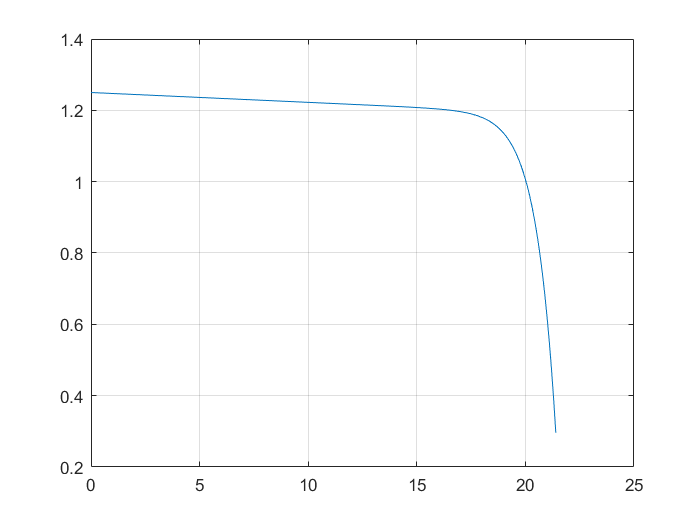

G=1000;
T=25;
Isc=1.25;
Voc=21.7;
A=0.97;
Rs=1.3;
Rsh=362;
Ns=36;
Np=1;
k_i=0.102;
k_v=-0.36099;
i=0;
V=0:0.1:21.4;
I = pv_math(G,T,Isc,Voc,A,Rs,Rsh,Ns,Np,k_i,k_v,V,i);
figure()
plot(V,I)
grid on

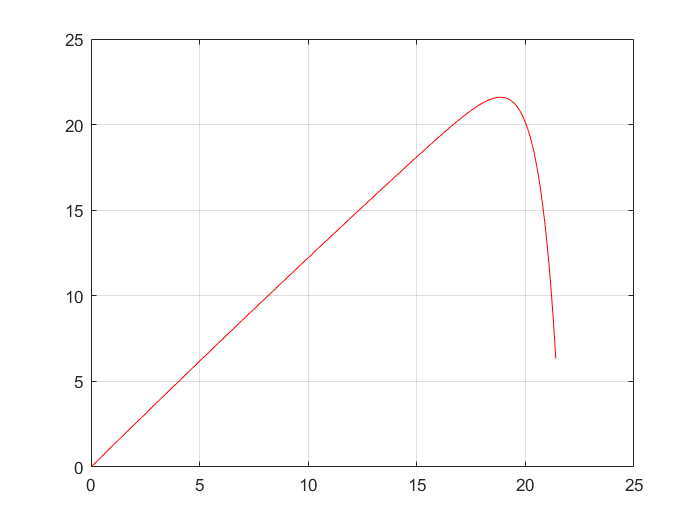

figure()
plot(V,V.*I,'r')
grid on

## IonSat MSP

Using the values of the MSP IonSat Solar panel 4S4P

G=1000;
T=25;
Isc=1.25;
Voc=21.7;
A=0.97;
Rs=1.3;
Rsh=362;
Ns=4;
Np=4;
k_i=0.102;
k_v=-0.36099;
i=0;
V=0:0.1:21.4;
I = pv_math(G,T,Isc,Voc,A,Rs,Rsh,Ns,Np,k_i,k_v,V,i);
figure()
plot(V,I)
grid on

### Variation of Temperature

### Variation with irradiance